1. e 2. Crie uma estrutura de dados (por exemplo, uma tabela) e guarde as seguintes informações relativas a cada áudio: a. diretório do áudio; b. nome do ficheiro (com extensão); c. participante; d. dígito; e. número da repetição. Desenvolva código para importação dos sinais de áudio e guarde o valor da taxa de amostragem e os sinais na estrutura de dados criada.

pastaAudios = 'audios';  
audios = dir(fullfile(pastaAudios, '*.wav'));

numeroAudios = length(audios);

%Estrutura de dados que armazena todas as informacoes relevantes dos 500 audios.
dados = struct('diretorio', "", 'nomeFicheiro', "", 'participante', 0, ...  
               'digito', 0, 'repeticao', 0, 'sinal', [], ...                
               'taxaAmostragem', 0, 'media', 0, 'desvioPadrao', 0, ...
               'intervaloTempo', 0, 'amplitudeMaxima', 0, 'energiaTotal', 0);

%Extração das informações presentes nos ficheiros de audio.           
for i = 1:numeroAudios                                   
    nomeFicheiro = audios(i).name;
    diretorio = fullfile(pastaAudios, nomeFicheiro);
    
    partesNome = split(nomeFicheiro, '_'); 
    
    digito = str2double(partesNome{1});      
    participante = partesNome{2};  
    
    partesRepeticao = split(partesNome{3}, '.');  
    repeticao = str2double(partesRepeticao{1});
    
    [sinal, taxaAmostragem] = audioread(diretorio);

    dados(i).diretorio = diretorio;
    dados(i).nomeFicheiro = nomeFicheiro;
    dados(i).participante = participante;
    dados(i).digito = digito;
    dados(i).repeticao = repeticao;
    dados(i).sinal = sinal;
    dados(i).taxaAmostragem = taxaAmostragem;
end

%Apenas para ser apresentavel.
tabela = struct2table(dados); 
disp(tabela);

          diretorio            nomeFicheiro      participante    digito    repeticao         sinal          taxaAmostragem       media        desvioPadrao    intervaloTempo    amplitudeMaxima    energiaTotal
    ______________________    _______________    ____________    ______    _________    ________________    ______________    ____________    ____________    ______________    _______________    ____________

    {'audios\0_33_0.wav' }    {'0_33_0.wav' }       {'33'}         0           0        {33565×1 double}        48000         {[       0]}    {[       0]}     {[       0]}    

3. Reproduza e represente graficamente um exemplo dos sinais importados, identificando o dígito e o número da repetição a que cada um corresponde, e indicando o eixo horizontal com o tempo em segundos.

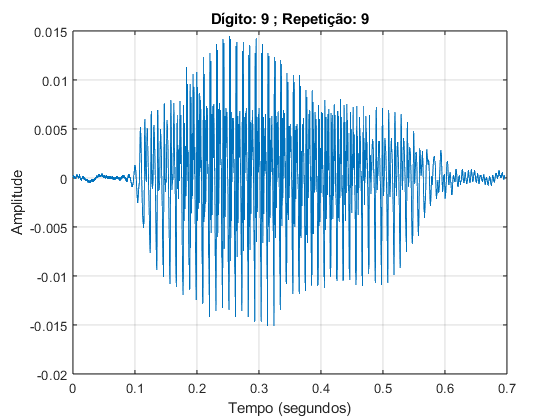

i = 500; %i = input('Linha: '); 
audio = dados(i);
plotarGrafico(audio);

4. e 5. Uma estratégia que pode melhorar a diferenciação entre dígitos é fazer uma etapa de préprocessamento para garantir que todos os ficheiros têm a mesma duração e intervalo de amplitude. Para isso deverá implementar os seguintes passos: 

-Retirar o “silêncio” inicial dos sinais, de forma a garantir que todos começam exatamente ao mesmo tempo (por exemplo, através do estudo da Energia do sinal ao longo do tempo).

 -Normalizar a amplitude com base na amplitude máxima e mínima das amostras. Isto garante que os problemas usuais da gravação do som (por exemplo, a distância da pessoa ao microfone) não interferem na análise. 

-Adicionar (ou retirar) silêncio no fim dos ficheiros para garantir que todos têm a mesma duração total. Guarde os sinais após o pré-processamento na estrutura de dados criada no ponto 1.

Para os sinais obtidos após o pré-processamento, repita o ponto 3. 

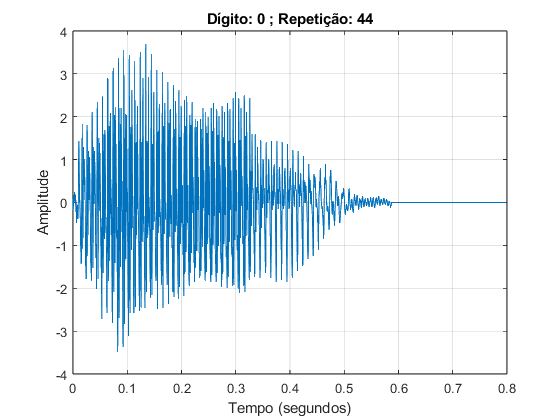

tamanhoAudio = 38400; %Valor que limita o tamanho do vetor de amplitudes de modo a todos os audios terem a mesma duração.
limiteEnergia = 0.001; %Valor de energia minima utilizado para detetar quando o ator começa a falar.

for i = 1:numeroAudios
    sinal = dados(i).sinal;  
    
    % Remover silêncio no início.
    energia = movsum(abs(sinal).^2, 1000);                        
    indiceInicio = find(energia > limiteEnergia, 1, 'first');
    sinal = sinal(indiceInicio:end);  

    % Normalizar a amplitude do sinal.
    sinal = (sinal - mean(sinal)) / std(sinal);                                   

    % Colocar a mesma duração para todos os audios.
    if length(sinal) < tamanhoAudio                               
        sinal = [sinal; zeros(tamanhoAudio - length(sinal), 1)];
    else
        sinal = sinal(1:tamanhoAudio);
    end

    dados(i).sinal = sinal;
end

%Apresentar audio após processamento.
i = 40; %i = input('Linha: '); 
audio = dados(i);
plotarGrafico(audio);

6. Compare os gráficos obtidos para cada dígito nos pontos 3 e 5, e identifique visualmente possíveis características temporais que permitam a diferenciação entre dígitos.

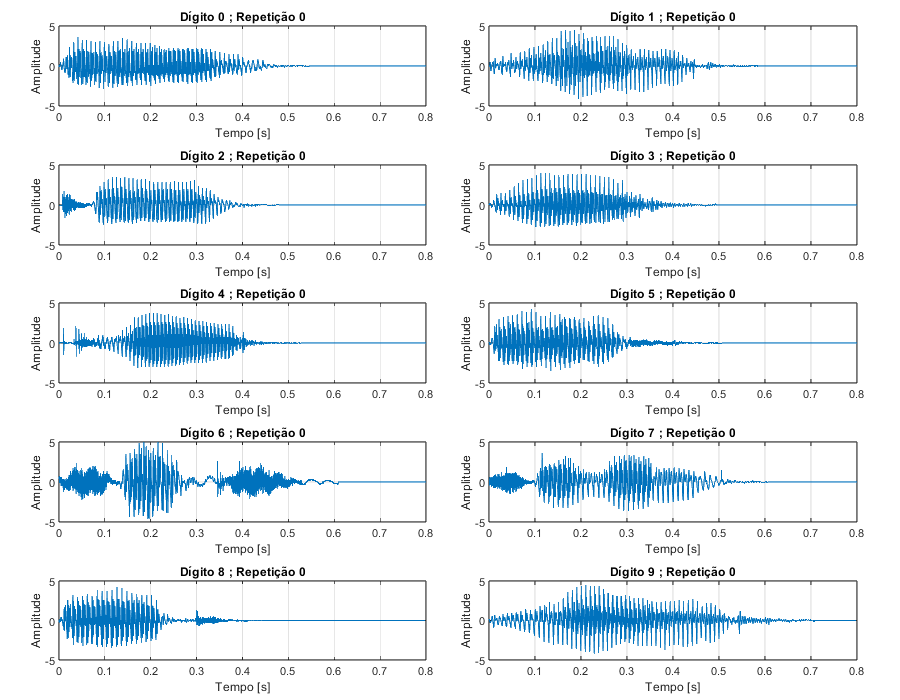

%As diferençcas entre os dois gráficos são as seguintes: o valor das amplitudes, a duração do audio e a 
% posição do grafico em relação ao tempo.
% Digitos como 1, 5, 7, 8 e 9 tem uma maior amplitude maxima, enquanto
% digitos como 2 e 4 tem uma menor amplitude maxima.
% Outro exemplo é nos Digitos 6, 7 e 9 têm uma duração de 0.6 segundos
% enquanto digitos como o 8 tem 0.4 segundos.

%Apresentação de todos os digitos para observar diferenças visuais dos sinais.
repeticao=0; %repeticao = input('Repeticao: ');
plotarGraficosJuntos(dados,repeticao);

7. Implemente o cálculo de possíveis características (features) temporais do sinal que permitam a diferenciação entre dígitos, como energia (total, por intervalos temporais, diferenças entre intervalos, etc.), amplitude (máxima, mínima, razão de amplitudes, desvio padrão, etc.) ou outras medidas temporais que considere relevantes.

Deverá efetuar o cálculo para cada áudio de pelo menos 5 características temporais e guardar na estrutura de dados criada no ponto 1.   

%As caracteristicas escolhidas foram: media, desvio padrão, energia total, amplitude maxima e intervalo de tempo (ou duracao do digito).
for i = 1:numeroAudios
    sinal = dados(i).sinal;  
    
    energia = movsum(abs(sinal).^2, 1000); 
    indicesFala = find(energia > limiteEnergia); 
    
    intervaloTempo = (indicesFala(end) - indicesFala(1)) / dados(i).taxaAmostragem; 
    
    dados(i).intervaloTempo = intervaloTempo;
    
    dados(i).energiaTotal = sum(abs(sinal).^2); 
    dados(i).amplitudeMaxima = max(abs(sinal)); 
    dados(i).media = mean(sinal);
    dados(i).desvioPadrao = std(sinal);
end

%Apenas para ser apresentavel.
tabela = struct2table(dados); 
disp(tabela);

          diretorio            nomeFicheiro      participante    digito    repeticao         sinal          taxaAmostragem       media       desvioPadrao    intervaloTempo    amplitudeMaxima    energiaTotal
    ______________________    _______________    ____________    ______    _________    ________________    ______________    ___________    ____________    ______________    _______________    ____________

    {'audios\0_33_0.wav' }    {'0_33_0.wav' }       {'33'}         0           0        {38400×1 double}        48000         -3.0141e-19      0.82531          0.55531          

8. Recorrendo à representação gráfica das características temporais extraídas no ponto anterior, identifique as três características que permitem uma melhor discriminação dos dígitos. Para isto pode utilizar boxplots, gráficos 2D, 3D, etc. Alguns exemplos são apresentados na Figura 3. Indique as características escolhidas. 

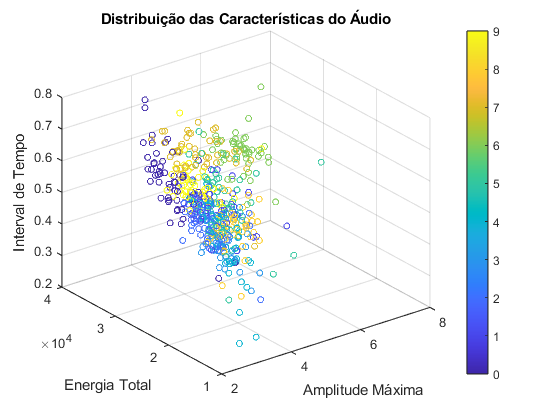

valores1 = zeros(numeroAudios, 1);
valores2 = zeros(numeroAudios, 1);
valores3 = zeros(numeroAudios, 1);
digitos = zeros(numeroAudios, 1);

for i = 1:numeroAudios
    valores1(i) = dados(i).amplitudeMaxima;
    valores2(i) = dados(i).energiaTotal;
    valores3(i) = dados(i).intervaloTempo;
    digitos(i) = dados(i).digito;
end

figure;
scatter3(valores1, valores2, valores3, 20, digitos, 'o'); % Gráfico de dispersão 3D
xlabel('Amplitude Máxima');
ylabel('Energia Total');
zlabel('Interval de Tempo');
grid on;
title('Distribuição das Características do Áudio');
colorbar; % Adiciona uma barra de cores para visualizar os dígitos

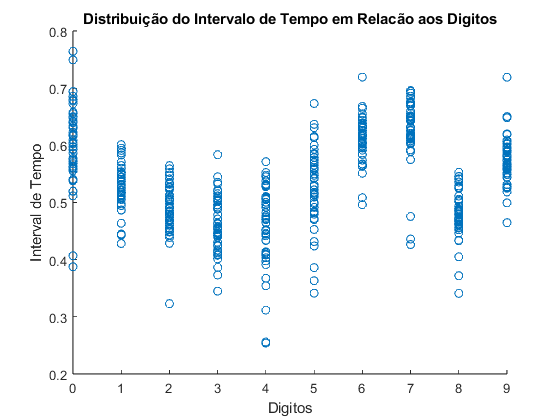

scatter(digitos,valores3,'o'); % Gráfico de dispersão 2D
xlabel('Digitos');
ylabel('Interval de Tempo');
title('Distribuição do Intervalo de Tempo em Relacão aos Digitos');

9. Remova da estrutura de dados criada no ponto 1 os sinais de áudio importados e guarde a estrutura de dados num ficheiro “.mat”.

save('dados.mat',"dados")